clc; clear;

global kappa m_ball g alpha_0 d_ball
y_0 = 30*10^-2;
l = 180*10^-2;
alpha_0 = 40;
v_0 = 3.8;
g = 9.81;
c_w = 0.47;
roh = 1.2;
s_becher = 0.5*10^-2;
d_becher = 9.5*10^-2;
d_ball = 50;
t_start = 0;
t_final = 30;
bounces = 3;
m_ball = 20;
refine = 10;
% Luftwiderstandskonstante
kappa = roh*(d_ball*10^-3)^2*pi*c_w/8;


options = odeset('Events',@events,...
   'Refine',refine);

x0=0;
x0prime=v_0*cosd(alpha_0); 
y0=y_0;
y0prime=v_0*sind(alpha_0);
y0_=[x0; x0prime; y0; y0prime];

tout = t_start;
yout = y0_.';
teout = [];
yeout = [];
ieout = [];



% Loop Block
for bounce=1:bounces
    
    [t,y,te,ye,ie] = ode45(@f,[t_start t_final],y0_,options);

    nt = length(t);
    
    tout = [tout; t(1:nt)];
    yout = [yout; y(1:nt,:)];
    teout = [teout; te];          % Events at tstart are never reported.
    yeout = [yeout; ye];
    ieout = [ieout; ie];
    
    y0_(1) = y(nt,1);
    y0_(2) = y(nt,2);
    y0_(3) = 0;
    y0_(4) = -y(nt,4);
    
    tstart = t(nt);
 
end
yout

yout =                          0          2.91096888385212                       0.3          2.44259291680885
                         0          2.91096888385212                       0.3          2.44259291680885
      2.00950841550954e-05          2.91096676977944         0.300016861556203           2.4425269700043
      4.01901537163479e-05          2.91096465573278          0.30003372265716          2.44246102313132
      6.02852086839371e-05          2.91096254171214         0.300050583302869           2.4423950761899
      8.03802490580428e-05          2.91096042771751         0.300067443493332          2.44232912918004
      0.000100475274838844          2.91095831374891         0.300084303228547          2.44226318210176
      0.000120570286026522          2.91095619980632         0.300101162508514          2.44219723495504
      0.000140665282621254          2.91095408588975         0.300118021333232          2.44213128773989
      0.000160760264623221          2.9109519719

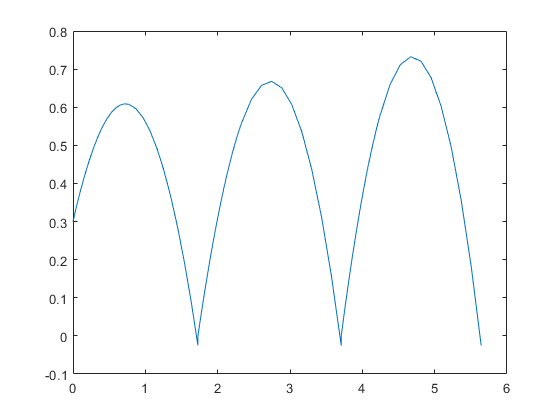

plot(yout(:,1),yout(:,3))

function dydt = f(t,y)
global kappa m_ball g
x_p = y(2);
x_pp = -kappa*sqrt(y(2)^2+y(4)^2)*y(2)/(m_ball*10^-3);
y_p = y(4);
y_pp = (kappa*sqrt(y(2)^2+y(4)^2)*y(4)/(m_ball*10^-3))-g;
dydt = [x_p;x_pp;y_p;y_pp];
end

function [value,isterminal,direction] = events(t,y)
global d_ball
d = d_ball*10^-3;
value = y(3)+d/2;     % detect height = 0
isterminal = [1 0];   % stop the integration
direction = -1;   % negative direction
end